# DSZOB, cvičenie 5.

## **Zadanie:**

## **Úloha 1 **Analýza signálu

**Nasnímajte signál zvuku ladičky. **

Vizualizujte nasnímaný signál v priestorovej doméne. Na základe vizualizácie vyberte vhodný úsek, vypočítajte a vizualizujte pre ne Fourierovu transformáciu:

- Cez funkciu **fft** na malej vzorke dát (napr. 512)

- Prepočítajte index spektrálneho koeficienta na frekvenciu pre najväčsiu hodnotu v grafe

- Cez funkciu **spectrogram**

- Zistite dominantnú frekvenciu daného signálu a vyznačte ju v grafe.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

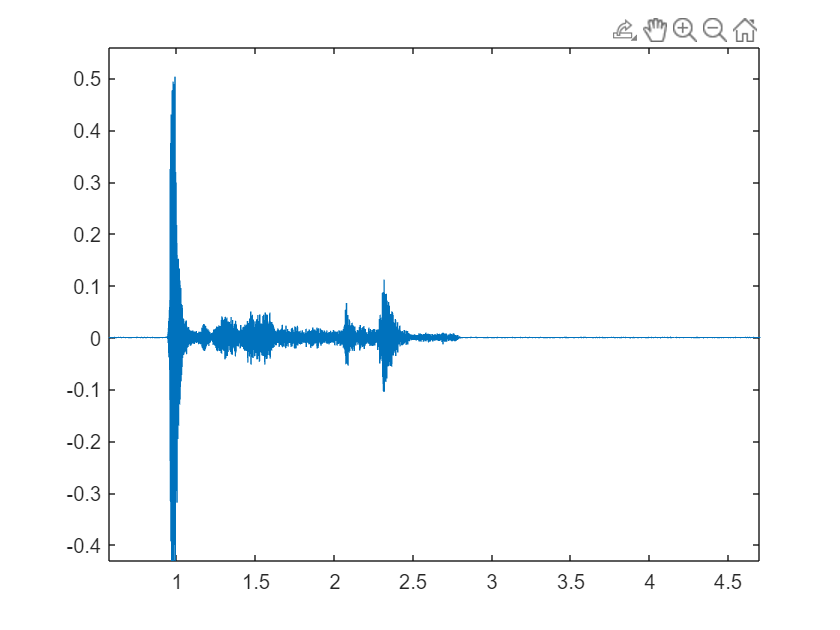

fs = 44100;
recorder = audiorecorder(fs,16,1);
recordblocking(recorder,5);
y = getaudiodata(recorder)';
x = 0:1/fs:5;
x = x(1:220500);
plot(x,y)

Prepísal som si načítaný zvuk medzičasom, takže popis len takto: 

title - Nameraný signál z ladičky

y - magnitude

x - time[s]

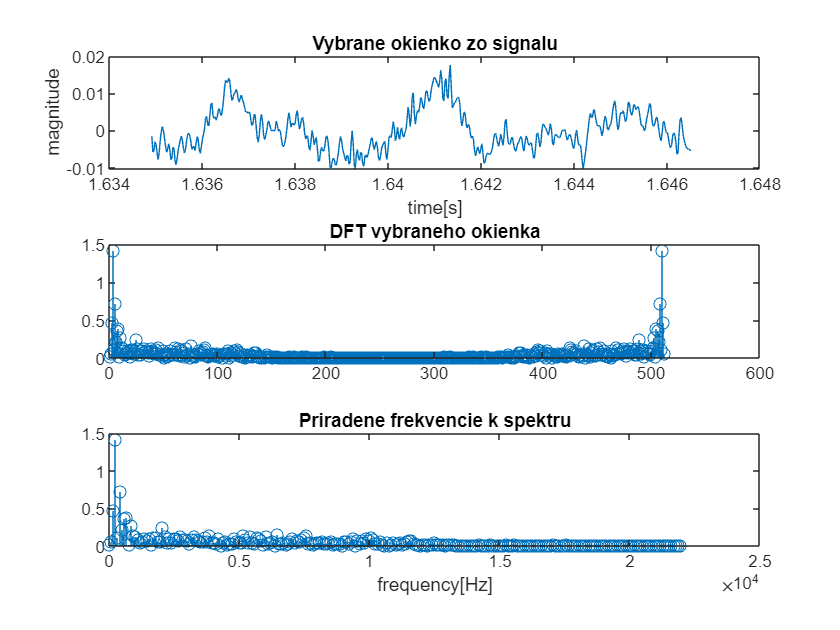

y_512 = y(72101:72612);
x_512 = x(72101:72612);
figure();
subplot(3,1,1);
plot(x_512, y_512)
title('Vybrane okienko zo signalu')
xlabel('time[s]')
ylabel('magnitude')
subplot(3,1,2);
dft = abs(fft(y_512));
stem(dft)
title('DFT vybraneho okienka')
subplot(3,1,3);
shifted = fftshift(dft);
shifted = shifted(257:512);
x_hz = 1:(fs/2)/256:fs/2;
stem(x_hz, shifted)

title('Priradene frekvencie k spektru')
xlabel('frequency[Hz]')

[M,I] = max(shifted);

ans = 259.3984

x_hz(I)

V analyzovanom úseku bola dominantná frekvencia približne 259 Hz.

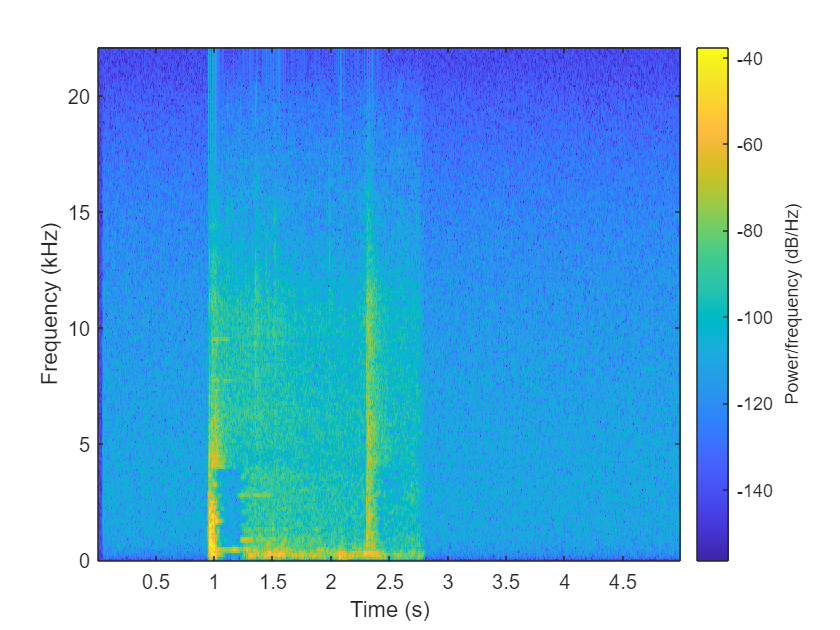

figure();
spectrogram(y,hamming(512), 256, 512, 44100, 'yaxis')

Dominantná frekvencia je na spektrograme vidieť ako výrazná vodorovná žltá čiara v spodnej časti. Síce spektrogram nevišiel dokonale a čiaranie nie je úplne súvislá, ale jej hodnota je približne 430 Hz. To +- zodpovedá frekvencii ladičky, ktorá bola 440 Hz. 

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

- Načítajte zvukovú stopu (napr. hudbu z dokumentového serveru) ako signál.

- Vizualizujte signál (celý aj detail okienka použitého v bode 3).

- Spočítajte kosínovú transformáciu (*dct*) aspoň pre jedno okienko a vizualizujte spektrum okienka (použite funkciu matlabu *stem*).

- Za pomoci cyklu *for* prejdite celým signálom tak, že vyberiete okienka bez prekryvu.

- Pre jednotlivé okienka vypočítajte *dct*, nastavte amplitúdy spektrálnych koeficientov, ktoré sú menšie ako zvolený prah (teda všetko, čo má menšiu amplitúdu ako zvolený prah) na hodnotu 0 a vypočítajte spätnú kosínovú transformáciu (*idct*). Takto získate nový, filtrovaný signál.

- Vizualizujte spektrum signálu pred a po filtrácií formou spektrogramu.

Vypočujte si výstupný, filtrovaný signál s rôznymi prahmi nulovania spektrálnych koeficientov. Porovnajte. Pri akej hodnote prahu došlo k značnému znehodnoteniu kvality zvukovej stopy?

[y,Fs] = audioread('Fado1.wav');
x = 0:1/Fs:length(y)/Fs;
x = x(1:882000);

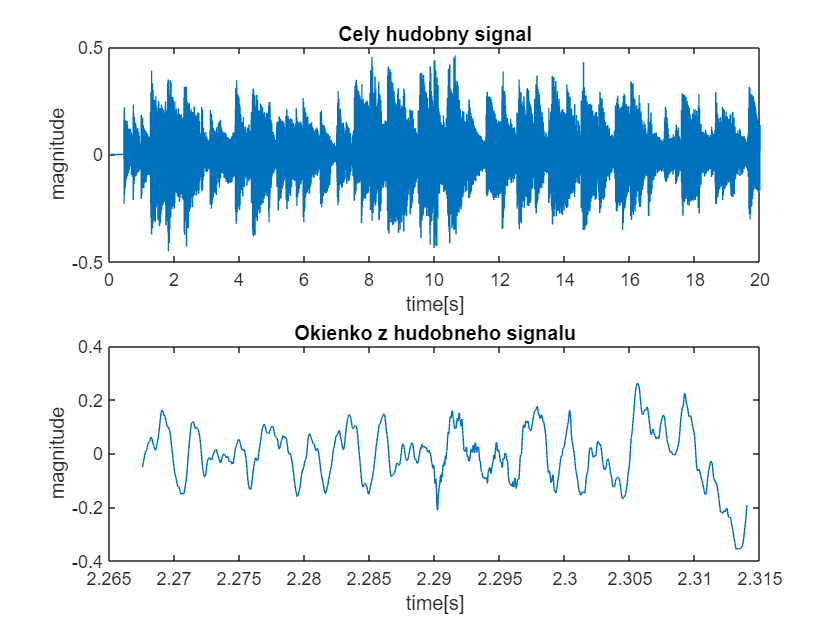

figure();
subplot(2,1,1);
plot(x,y)
title('Cely hudobny signal')
ylabel('magnitude')
xlabel('time[s]')
subplot(2,1,2);
y_window = y(100001:102048);
x_window = x(100001:102048);
plot(x_window, y_window)
title('Okienko z hudobneho signalu')
ylabel('magnitude')
xlabel('time[s]')

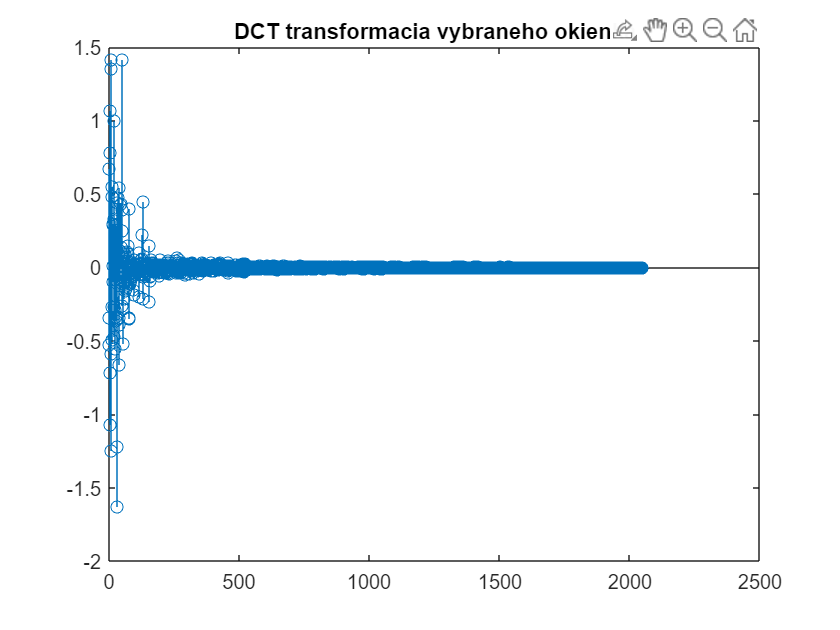

figure();
dct_1 = dct(y_window);
stem(dct_1)
title('DCT transformacia vybraneho okienka')

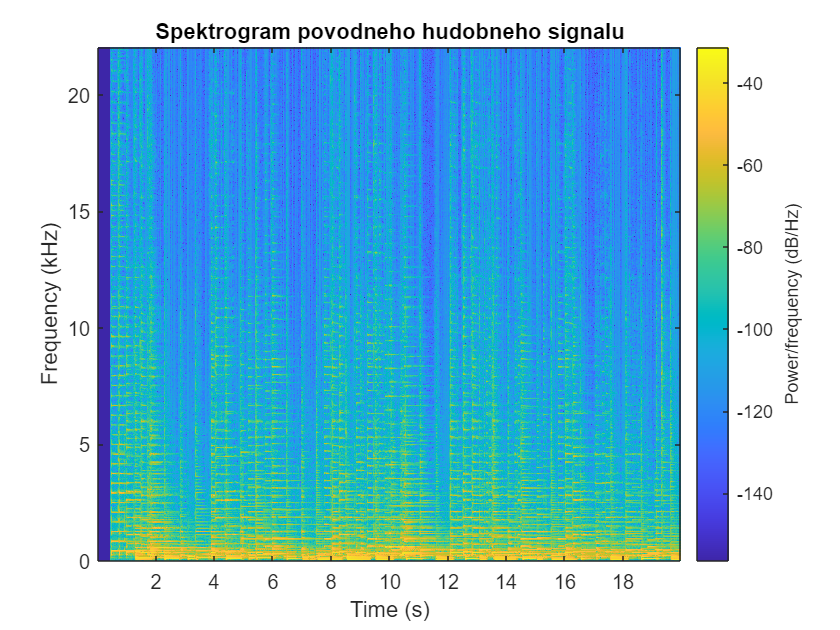

figure();
spectrogram(y,hamming(2048), 1024, 2048, 44100, 'yaxis')
title('Spektrogram povodneho hudobneho signalu')

%sound(y, Fs)

figure();
subplot(2,1,1);
y_filter_010 = custom_dct_filter(y, 0.1);
spectrogram(y_filter_010, hamming(2048), 1024, 2048, 44100, 'yaxis')
title('Spektrogram po filtracii - threshold: |spektralny koeficient| < 0.1')
subplot(2,1,2);
plot(x(100001:102048), y_filter_010(100001:102048))
title('Okienko po filtracii - threshold: |spektralny koeficient| < 0.1')
ylabel('magnitude')
xlabel('time[s]')

%sound(y_filter_010, Fs)

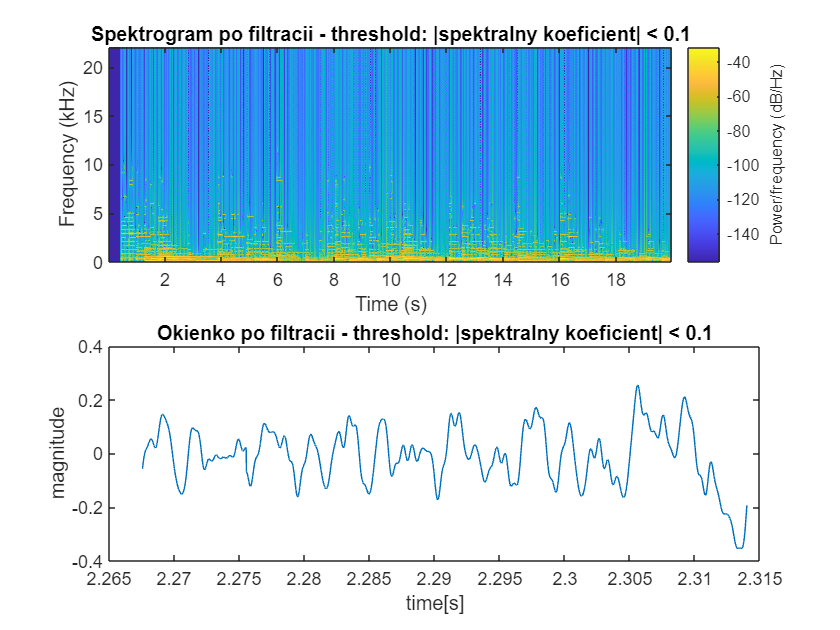

figure();

subplot(2,1,1);
y_filter_025 = custom_dct_filter(y, 0.25);
spectrogram(y_filter_025, hamming(2048), 1024, 2048, 44100, 'yaxis')
title('Spektrogram po filtracii - threshold: |spektralny koeficient| < 0.25')
subplot(2,1,2);
plot(x(100001:102048), y_filter_025(100001:102048))
title('Okienko po filtracii - threshold: |spektralny koeficient| < 0.25')
ylabel('magnitude')
xlabel('time[s]')

%sound(y_filter_025, Fs)

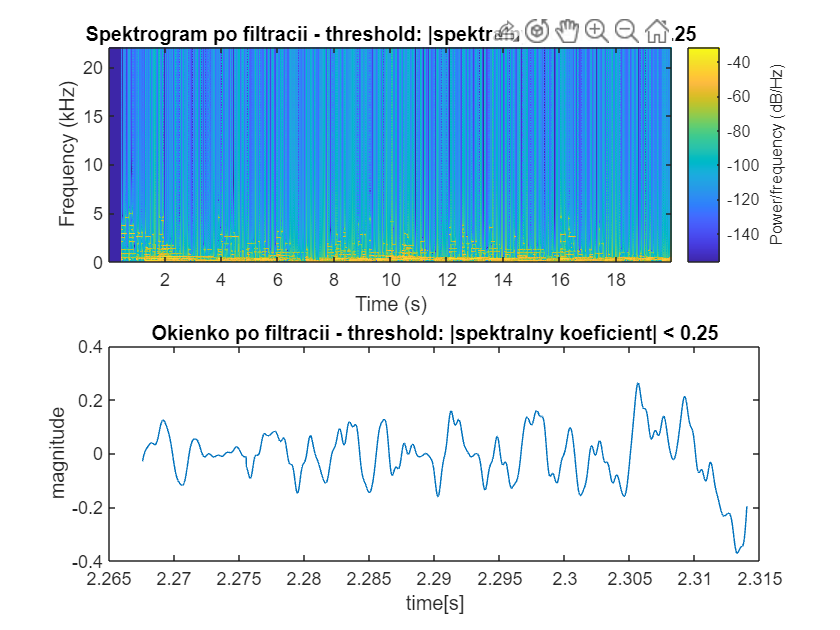

figure();
subplot(2,1,1);
y_filter_050 = custom_dct_filter(y, 0.5);

spectrogram(y_filter_050, hamming(2048), 1024, 2048, 44100, 'yaxis')
title('Spektrogram po filtracii - threshold: |spektralny koeficient| < 0.5')
subplot(2,1,2);
plot(x(100001:102048), y_filter_050(100001:102048))
title('Okienko po filtracii - threshold: |spektralny koeficient| < 0.5')
ylabel('magnitude')
xlabel('time[s]')

%sound(y_filter_050, Fs)

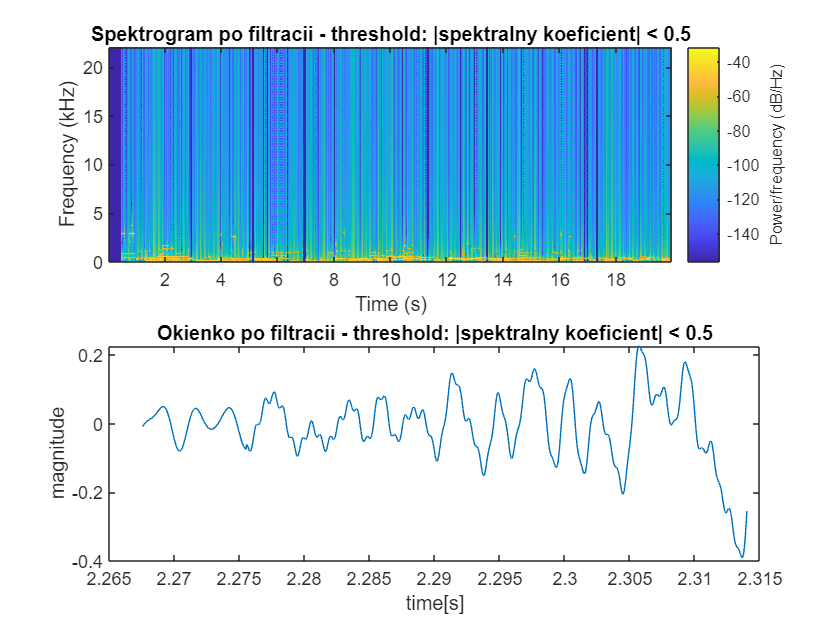

figure();
subplot(2,1,1);
y_filter_075 = custom_dct_filter(y, 0.75);
spectrogram(y_filter_075, hamming(2048), 1024, 2048, 44100, 'yaxis')
title('Spektrogram po filtracii - threshold: |spektralny koeficient| < 0.75')

subplot(2,1,2);
plot(x(100001:102048), y_filter_075(100001:102048))
title('Okienko po filtracii - threshold: |spektralny koeficient| < 0.75')
ylabel('magnitude')
xlabel('time[s]')

%sound(y_filter_075, Fs)

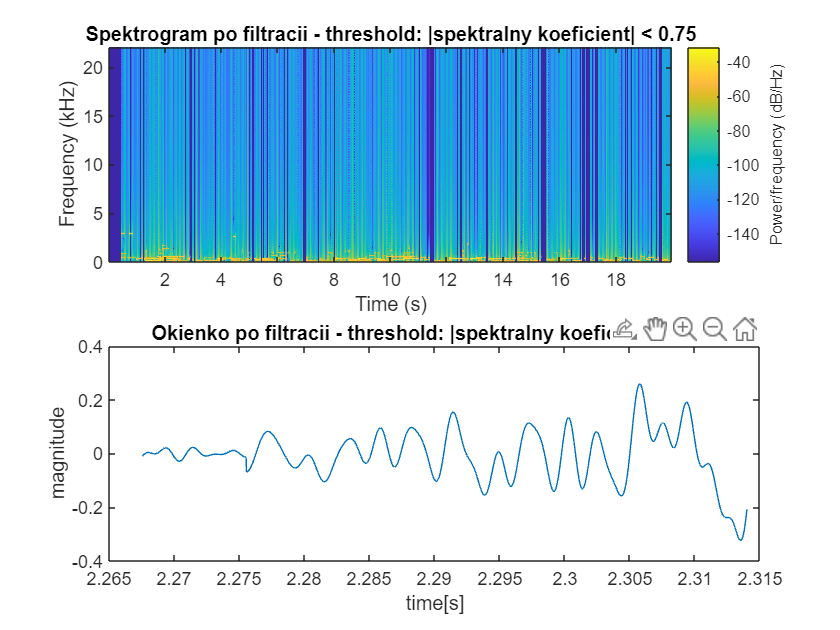

figure();
subplot(2,1,1);
y_filter_100 = custom_dct_filter(y, 1);
spectrogram(y_filter_100, hamming(2048), 1024, 2048, 44100, 'yaxis')
title('Spektrogram po filtracii - threshold: |spektralny koeficient| < 1.0')
subplot(2,1,2);
plot(x(100001:102048), y_filter_100(100001:102048))

title('Okienko po filtracii - threshold: |spektralny koeficient| < 1.0')
ylabel('magnitude')
xlabel('time[s]')

%sound(y_filter_100, Fs)

## Komentár:

Na spektrogramoch vidíme, že postupným zvyšovaním hodnôt spektrálnych koeficientov od ktorých sú tieto koeficienty ignorované, že sa strácajú násobné frekvencie a že v niektorých časových úsekoch dokonca nie sú žiadne frekvencie.

Zároveň na vizualizovaných filtrovaných signáloch vidíme, že zvyšovaním hranice filtra sa signál stáva stále "jednoduchším" (strácajú sa niektoré vyššie frekvencie) a v poslednom prípade, keď berieme do úvahy len hodnoty vyššie ako 1 (v absolútnej hodnote), prefiltrovaný signál už v podstate vôbec nezodpovedá poslednému.

Znížená kvalita zvuku je pozorovateľná miernym praskaním a hluchými miestami už aj pri najjemnejšom filtri. Tento jav sa stáva stále markantnejším, ale základné dominantné frekvencie sú jasne rozoznateľné aj pri poslednom, najprísnejšom, filtri.

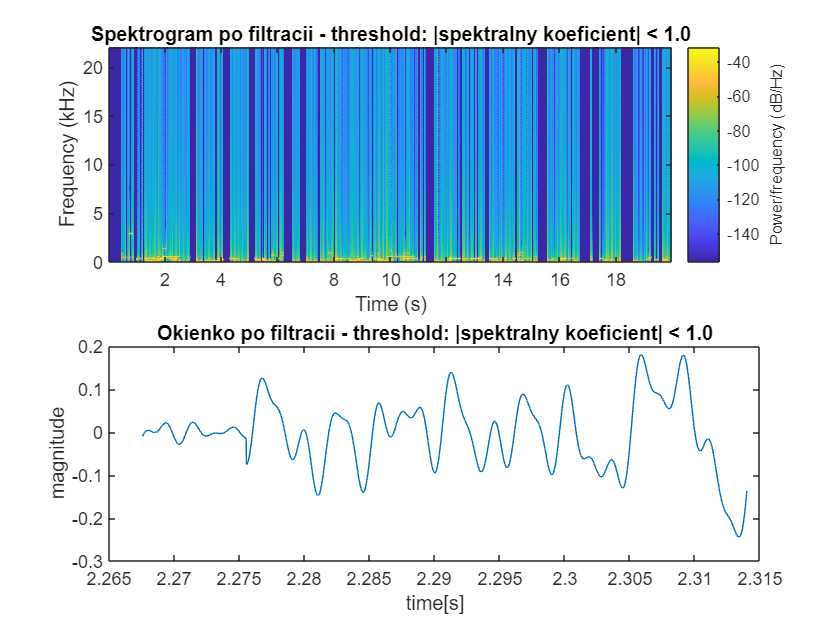

function transformed = custom_dct_filter(y, threshold)
    % Pre zvolenu velkost okienka (2048), je mozne signal
    % rozdelit na 430 celych okienok a 431. je doplnene
    % nulami na tuto dlzku (aby sa dosiahla velkost
    % mocniny 2 a aby sa to lahsie pocitalo)
    tmp_y = zeros(1, 431*2048);
    tmp_y(1:882000) = y;
    transformed = zeros(1, length(tmp_y));
    for index = 1:2048:length(tmp_y)

        dct_1 = dct(tmp_y(index: index + 2048 -1));
        dct_1(abs(dct_1) < threshold) = 0;
        transformed(index: index + 2048 -1) = idct(dct_1);
    end
    % Vysledny signal je vracany v povodnej dlzke
    transformed = transformed(1:882000);
end